% page 144, sqrtifexamp.m

num = input('Enter a number: ')
if num < 0
    num = 0
end

fprintf('The square root of %.2f is %.1f',num,sqrt(num))

% page 144, practice 4.1

hours = input('Enter your current amount of working hours: ')
if hours > 40
    disp('Hey, you get overtime!')
end
if hours == 40
    disp('Congrats, you just hit the overtime limit!')
end
if hours < 40
    disp('Sorry, no overtime yet!')
end

% page 145, quick question

v1 = createvec(5,10)
v2 = createvec(10,5)

% page 147, practice 4.2

angle = input('Enter the angle: ')
unit = input('(r)adians as default or (d)egree: ','s')
if unit == 'r' || unit == 'R'
    fprintf('Sine(%.2f) = %.2f\n',angle,sin(angle))
else
    fprintf('Sine(%.2f) = %.2f\n',angle,sind(angle))
end

% page 148, checkradius

radius = input('Enter radius: ')
if radius < 0
    error('Sorry, %.2f is not a valid radius\n',radius)
end

% page 149, nested if-clauses
% y = 1   if       x <  1
% y = x^2 if -1 <= x <= 2
% y = 4   if       x >  2

for x = 0:0.2:5
    if x < 1
        y = 1;
        fprintf('%.1f - %.1f\n',x,y)
    else
        if x >= 1 && x <= 2
            y = x^2;
            fprintf('%.1f - %.1f\n',x,y)
        else
            y = 4;
            fprintf('%.1f - %.1f\n',x,y)
        end
    end
end

% page 152, quick question

data = input('Enter a arbitrary numerical datatype (scalar, vector or matrix): ');
[r,c] = size(data);
if r == 1 && c == 1
    disp('Your datatype is a scalar')
elseif r == 1 || c == 1
    disp('Your datatype is a vector')
else
    disp('Your datatype is a matrix')
end

% page 153, practice 4.3

data = input('Enter a arbitrary numerical datatype (scalar, vector or matrix): ');
[r,c] = size(data);
if r == 1 && c == 1
    out = 'scalar';
elseif r == 1 && c > 1
    out = 'row vector';
elseif c == 1 && r > 1
    out = 'column vector';
else
    out = 'matrix';
end 
disp(data)
fprintf('is a %s\n',out)

% page 154, example

quiz = input('Enter your point: ')

quiz = 7

switch quiz
    case {10,9}
        grade = 'A';
    case 8
        grade = 'B';
    case 7
        grade = 'C';
    case 6
        grade = 'D';
    otherwise 
        grade = 'F';
end
fprintf('Your grade is %s\n',grade)

Your grade is C


% page 158, quick question

ismyletter('a')

ans = 1

ismyletter('A')

ans = 1

ismyletter('z')

ans = 1

ismyletter('Z')

ans = 1

ismyletter('4')

ans = 0

% page 159, practice 4.5

mystr = input('Enter a string: ')


mystr =

     []



if mystr ~isempty(mystr)
    fprintf('Your string goeslike this: %s\n',mystr)
else
    disp('You entered an empyt srtring!')
end

You entered an empyt srtring!


% page 180, createmulttab.m

num_rows = input('Enter number of rows: ')
num_cols = input('Enter number of cols: ')

multmatrix = multtable(num_rows,num_cols)
save multmatrix.dat multmatrix -ascii

% page 181, practice 5.3

mat = [7 11 3; 3:5];
[r, c] = size(mat);

for i = 1:r
    fprintf('The sum is %d\n',sum(mat(i, :)))
end

The sum is 21
The sum is 12



for i = 1:2
    fprintf('%d: ', i)
    for j = 1:4
        fprintf('%d ', j)
    end
    
    fprintf('\n')
end

1: 

1 2 3 4 

2: 

1 2 3 4 

% page 186, example
n = 20;
vec = round(rand(1,20) * 100,1);
mkr = -99 * randi([0 1],1,n);

for i = 1:n
    if mkr(i) ~= 0
        vec(i) = mkr(i);
    end
end

save experd.dat vec -ascii;
clear;

load experd.dat;
n=length(experd);

disp(experd)

  Columns 1 through 19

  -99.0000   36.4000   15.1000   15.0000   35.1000  -99.0000  -99.0000   48.7000   46.5000   13.1000  -99.0000  -99.0000   83.5000   65.6000  -99.0000  -99.0000  -99.0000   62.5000  -99.0000

  Column 20

  -99.0000



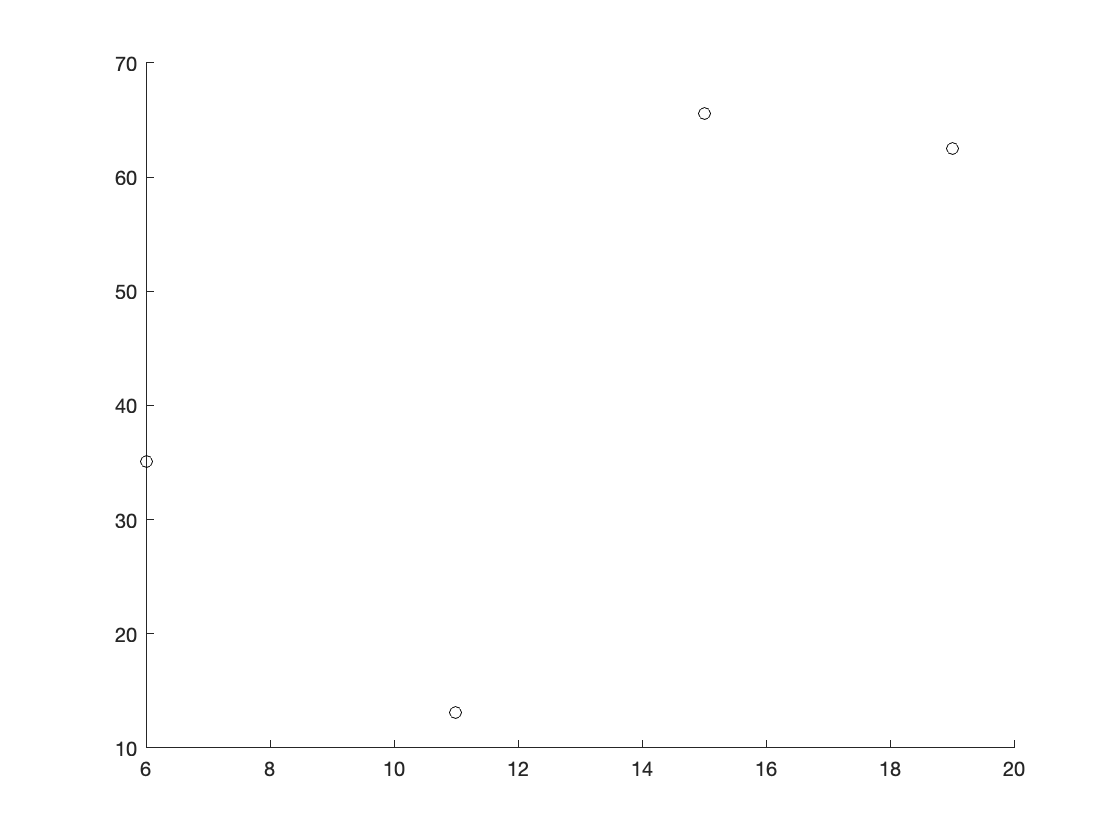

clf
hold on
for i=1:n
    if i > 1 && experd(i) == -99 && experd(i-1) ~= -99
       plot(i,experd(i-1),'ko')
    end
end

% page 193, example

num = input('Enter an integer: ');
numint = int32(num);

while num ~= numint
    num = input('Invalid, enter an integer: ');
    numint = int32(num);
end

fprintf('Thanks, you entered %d',numint)

Thanks, you entered -5

% page 195, example

% the programming concept
v = [3 7 2 1];
fact = 3;

for i = 1:length(v)
    v(i) = v(i) * 3;
end

disp(v)

     9    21     6     3




% the efficient concept
v = [3 7 2 1];
v = v * 3;
disp(v)

     9    21     6     3



% page 195, example

% the programming concept
n = 5

n = 5

fact = 1

fact = 1

for i = 1:n
    fact = fact * i
end

fact = 1

fact = 2

fact = 6

fact = 24

fact = 120

disp(fact)

   120




% the efficient concept
fact = prod(1:5)

fact = 120

% page 196, quick question

% cumulative sum
vec = [4 6 8 2 3 11 7];
runsum = 0

runsum = 0

mycumsum = zeros(size(vec));
for i = 1:length(vec)
    runsum = runsum + vec(i)
    mycumsum(i) = runsum;
end

runsum = 4

runsum = 10

runsum = 18

runsum = 20

runsum = 23

runsum = 34

runsum = 41

disp(mycumsum)

     4    10    18    20    23    34    41



% page 197, practice 5.7

% cumulative product
vec = [4 6 2 3 2];
cumprod(vec);
runprod = 1;
mycumpord = zeros(size(vec));
for i = 1:length(vec)
    runprod = runprod * vec(i);
    mycumprod(i) = runprod;
end
disp(mycumprod)

     4    24    48   144   288



cumprod(vec)

ans =      4    24    48   144   288


% page 197, quick question

% columnwiwe cumulative sum of a matrix
mat = randi([1 10],2,4)

mat =      6     5     1    10
     1     5     1     6



matcolsum(mat)

ans =      7    10     2    16


% page 198, practice 5.8

% rowiswe cumulative sum of a matrix
mat = randi([1 10],4,2)

mat =      7     2
     4     9
     2     7
     6     9



matrowsum(mat)

ans =      9
    13
     9
    15


% page 198, example
mat = randi([-10 +10],3,5)

mat =      0     9    -8     1     6
    -4     4     0     4    -2
     2     9    -8    -7     8



signum(mat)

ans =      0     1    -1     1     1
    -1     1     0     1    -1
     1     1    -1    -1     1


sign(mat)

ans =      0     1    -1     1     1
    -1     1     0     1    -1
     1     1    -1    -1     1


% page 199, example
mat = randi([-10 10],2,4)

mat =      1     8     7    -5
    -2     4    -8     6



mymin(mat)

ans = -8

min(mat)

ans =     -2     4    -8    -5
